# Disinflation under Monetary-led and Fiscal-led regime

clear all
close all
clc

## Creating Basic Struct

model_name = 'SW_LTB_RR';

eval(['dynare ', model_name, '.mod noclearall nostrict']) ;

Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Substitution of exo lags: added 1 auxiliary variables and equations.
Found 46 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.



STEADY-STATE RESULTS:

labobs           		 0.5509
robs             		 2.73374
pinfobs          		 2
dy               		 0.4
dc               		 0.4
dinve            		 0.4
dw               		 0.4
ewma             		 0
epinfma          		 0
zcapf            		 2.83203e-17
rkf              		 3.40868e-17
kf               		 -2.97612e-17
pkf              		 0
cf               		 -1.52583e-17
invef            		 -1.78152e-16
yf               		 -3.05026e-18
labf             		 6.89984e-18
wf               		 -2.57431e-18
rrf              		 1.36904e-16
mc               		 2.62483e-16
zcap             		 1.4261e-16
rk               		 1.71647e-16
k                		 5.3491e-15
pk               		 0
c                		 1.20058e-14
inve             		 5.20649e-15
y                		 8.44688e-15
lab              		 5.22958e-15
pinf             		 2
w                		 2.91168e-16
r                		 -3.80338e-16
a                		 0
b                		 1.68477e-17
g                		 3.7881e-

MODEL SUMMARY

  Number of variables:         46
  Number of stochastic shocks: 8
  Number of state variables:   23
  Number of jumpers:           14
  Number of static variables:  15


MATRIX OF COVARIANCE OF EXOGENOUS SHOCKS
Variables          ea        eb        eg       eqs        em     epinf        ew     eps_s
ea           0.213259  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eb           0.000000  3.427312  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eg           0.000000  0.000000  0.370881  0.000000  0.000000  0.000000  0.000000  0.000000
eqs          0.000000  0.000000  0.000000  0.362043  0.000000  0.000000  0.000000  0.000000
em           0.000000  0.000000  0.000000  0.000000  0.057456  0.000000  0.000000  0.000000
epinf        0.000000  0.000000  0.000000  0.000000  0.000000  0.021170  0.000000  0.000000
ew           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.043639  0.000000
eps_s        0.000000  0.000000  0.00


% dyn_to_str input struct
dyn_in.options_ = options_ ;
dyn_in.M_  = M_ ;
dyn_in.oo_ = oo_ ;
dyn_in.solve = 1 ;
dyn_in.linearize_around_diff_y = 0 ;

% Struct for KP process
SET.M_ = dyn_in.M_ ;
SET.oo_ = dyn_in.oo_ ;
SET.options_ = options_ ;

% Output from dyn_to_str
out = dyn_to_str(dyn_in) ;

SET.mats.Q = out.mats.Q ; 
Q = SET.mats.Q ;
SET.mats.G = out.mats.G ; 
G = SET.mats.G ;

SET.str_mats.A0 = out.mats.A ;
SET.str_mats.A1 = out.mats.B ;
SET.str_mats.B0 = out.mats.D ;
SET.str_mats.D0 = out.mats.E ;
SET.str_mats.D2 = out.mats.D2 ;
SET.str_mats.Gamma = out.mats.Gamma ;

## Extract variable details from Dynare output

n_ = M_.endo_nbr + 1 ; % Number of endogenous variables
l_ = M_.exo_nbr ;  % Number of exogenous variables
% n_ = n_+1 ;        % Constant

SET.variable.n_ = n_ ; 
SET.variable.l_ = l_ ; 
SET.nparam      = M_.param_nbr ;

var_names   = cellstr(M_.endo_names) ;
param_names = cellstr(M_.param_names) ;
exo_var_names = cellstr(M_.exo_names) ;

for ii=1:n_-1
    eval(['SET.variable.',var_names{ii},'=',int2str(ii),';']) ;
end

for ii=1:l_
    eval(['SET.variable.shock.',exo_var_names{ii},'=',int2str(ii),';']) ;
end

for ii=1:M_.param_nbr
    eval(['SET.param_names.',param_names{ii},'=',int2str(ii),';']) ;
end

SET.y_ss = (eye(n_-1) - Q(1:n_-1,1:n_-1)) \ Q(1:n_-1,end)  ;
SET.y_ss = [SET.y_ss ; 1] ; % Constant

## No ZLB Change in inflation target

cpie = 1; 1.005;
cr=cpie/(M_.params(SET.param_names.cbeta)*M_.params(SET.param_names.cgamma)^(-M_.params(SET.param_names.csigma)));

M_.params(SET.param_names.cpie) = cpie;
M_.params(SET.param_names.cr) = cr;
M_.params(SET.param_names.conster) = (cr-1)*100;
M_.params(SET.param_names.constepinf) = (cpie-1)*100;
M_.params(SET.param_names.crpi) = 0.5; 2.0443;
M_.params(SET.param_names.R) = 2.0443; 0.5;

[oo_.dr,info,M_,options_,oo_]  = resol(0,M_,options_,oo_) ;

dyn_in.options_ = options_ ;

dyn_in.M_  = M_ ;
dyn_in.oo_ = oo_ ;
dyn_in.solve = 1 ;
dyn_in.linearize_around_diff_y = 0 ;

SET1.M_ = dyn_in.M_ ;
SET1.oo_ = dyn_in.oo_ ;
SET1.options_ = options_ ;

out = dyn_to_str(dyn_in) ;

SET1.mats.Q = out.mats.Q ; Q = SET1.mats.Q ;
SET1.mats.G = out.mats.G ; G = SET1.mats.G ;

SET1.str_mats.A0 = out.mats.A ;
SET1.str_mats.A1 = out.mats.B ;
SET1.str_mats.B0 = out.mats.D ;
SET1.str_mats.D0 = out.mats.E ;
SET1.str_mats.D2 = out.mats.D2 ;
SET1.str_mats.Gamma = out.mats.Gamma ;

## ZLB regime

SET1.pos_of_i = SET.variable.r ; % Position of interest rate in mod file variable declaration
SET1.tr_row   = 22 ;   % Row (line number) of Taylor rule in mod file
SET1.zlb_val  = -M_.params(SET.param_names.conster); % Value of ihat at ZLB

% Structural matrices at ZLB
SET1.mat_i_f_zlb = SET1.str_mats ;

SET1.mat_i_f_zlb.A0(SET1.tr_row,:) = 0 ;
SET1.mat_i_f_zlb.A1(SET1.tr_row,:) = 0 ;
SET1.mat_i_f_zlb.D0(SET1.tr_row,:) = 0 ;
SET1.mat_i_f_zlb.B0(SET1.tr_row,:) = 0 ;
SET1.mat_i_f_zlb.A0(SET1.tr_row,SET1.pos_of_i) = 1 ;
SET1.mat_i_f_zlb.A0(SET1.tr_row,end) = -SET1.zlb_val ; % Constant

SET1.mat_init    = SET1.str_mats ; % Structural matrices not at ZLB
SET1.mat_fin     = SET1.str_mats ; % Structural matrices after ZLB

% SET.zlb.Qf          = SET.mats.Q ; 
% SET.zlb.mat_init    = SET.mat_init ; 
SET1.zlb.mat_i_f_zlb = SET1.mat_i_f_zlb ;
A0Z = SET1.mat_i_f_zlb.A0;
A1Z = SET1.mat_i_f_zlb.A1;
B0Z = SET1.mat_i_f_zlb.B0;
D0Z = SET1.mat_i_f_zlb.D0;
AZ = A0Z\A1Z;

A0Zinv = inv(A0Z);

BZ = A0Z\B0Z;


T = 50;
Tzs = 2;
Tze = T;


QZ = zeros(n_,n_,Tze-Tzs);
GZ = zeros(n_,l_,Tze-Tzs);

QZ(:,:,end) = (A0Z-B0Z*SET1.mats.Q)\A1Z;
GZ(:,:,end) = SET1.mats.G;

% Sequence of reduced form matrices
for t = Tze-Tzs-1:-1:1
    QZ(:,:,t) = (A0Z-B0Z*QZ(:,:,t+1))\A1Z;
    GZ(:,:,t) = (A0Z-B0Z*QZ(:,:,t+1))\D0Z;
end

## Disinflation Simulation

% T = 50; %length of the simulation
Ta = 4; %Date of the announcement
Tstar = 6; %Date of the disinflation policy implementation

y_non = zeros(n_,T);
y_non(:,1) = SET.y_ss;

if Ta<Tstar

% Allow for announcement date and implementation date to differ
% Do backward induction
Qat = zeros(n_,n_,Tstar-Ta);
Gat = zeros(n_,l_,Tstar-Ta);


% A0 y_t = A1 y_t-1 + B0 E_t y_t+1 + D0 eps_t 

% A = A1/A0
% A = SET.str_mats.A0\SET.str_mats.A1;
% A0inv = inv(SET.str_mats.A0);
% % B = B0/A0
% B = SET.str_mats.A0\SET.str_mats.B0;
D0 = SET.str_mats.D0;
A0 = SET.str_mats.A0;
A1 = SET.str_mats.A1;
B0 = SET.str_mats.B0;
% y_t = A y_t-1 + B E_t y_t+1 + D eps_t

%     Qat(:,:,end) = (eye(n_)-B*SET1.mats.Q)\A;
%     Gat(:,:,end) = (eye(n_)-B*SET1.mats.Q)\A0inv*D0;

Qat(:,:,end) = (A0-B0*SET1.mats.Q)\A1;
Gat(:,:,end) = (A0-B0*SET1.mats.Q)\D0;

% for t = Tstar-Ta-1:-1:1
%     Qat(:,:,t) = (eye(n_)-B*Qat(:,:,t+1))\A;
%     Gat(:,:,t) = (eye(n_)-B*Qat(:,:,t+1))\A0inv*D0;
% end

for t = Tstar-Ta-1:-1:1
    Qat(:,:,t) = (A0-B0*Qat(:,:,t+1))\A1;
    Gat(:,:,t) = (A0-B0*Qat(:,:,t+1))\D0;
end

Qtilde = zeros(n_,n_,Tstar-Ta);
Gtilde = zeros(n_,l_,Tstar-Ta);

% for t = 1:Tstar-Ta
%     Qtilde(:,:,t) = (eye(n_) - B*Qat(:,:,t))\A;
% end
for t = 1:Tstar-Ta
   Qtilde(:,:,t) = (A0-B0*Qat(:,:,t))\A1;
end


Qt = zeros(n_,n_,T);
Gt = zeros(n_,l_,T);

for t = 1:Ta
    Qt(:,:,t) = SET.mats.Q;
    Gt(:,:,t) = SET.mats.G;
end

for t = Ta:Tstar-1
    Qt(:,:,t) = Qtilde(:,:,t-Ta+1);
    Gt(:,:,t) = Gtilde(:,:,t-Ta+1);
end

for t = Tstar:T
    Qt(:,:,t) = SET1.mats.Q;
    Gt(:,:,t) = SET1.mats.G;
end

for t = 2:T
    y_non(:,t) = Qt(:,:,t) * y_non(:,t-1);
end

z_index = size(QZ, 3);

for t = 40:-1:6
    Qt(:,:,t) = QZ(:,:,z_index);
    Gt(:,:,t) = GZ(:,:,z_index);
    z_index = z_index - 1;
end

% Qt(:,:,32) = QZ(:,:,end);
% Gt(:,:,32) = GZ(:,:,end);
% 
% Qt(:,:,31) = QZ(:,:,end-1);
% Gt(:,:,31) = GZ(:,:,end-1);

for t = 2:T
    y_non(:,t) = Qt(:,:,t) * y_non(:,t-1);
end

else
for t= 2:Ta-1
    y_non(:,t) = SET.mats.Q*y_non(:,t-1); 
end

for t= Tstar:T
    y_non(:,t) = SET1.mats.Q*y_non(:,t-1); 
end

end

## Plotting

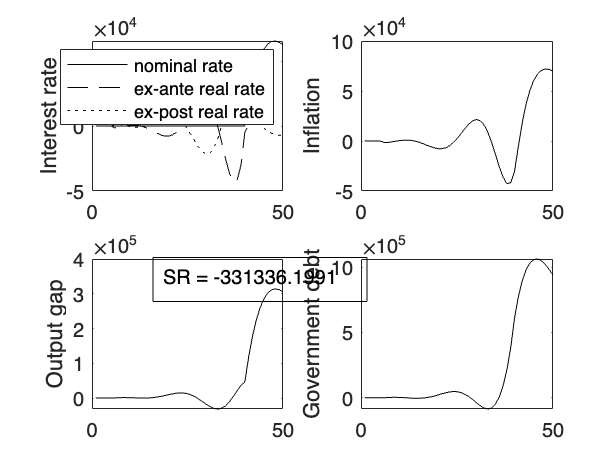

sacrifice_ratio = -sum((y_non(SET.variable.y,:))/(10-2));
sr_value_rounded = round(sacrifice_ratio, 4);

% Create the annotation with the text "SR = NUMBER"
annotation_text = sprintf('SR = %.4f', sr_value_rounded);
annotation_position = [0.25 0.34 0.25 0.1]; % [x, y, width, height] in normalized coordinates


figure(1)
subplot(2,2,1)
plot(y_non(SET.variable.robs,:),'k')
ylabel('Interest rate')
hold on
plot(y_non(SET.variable.rr,:),'k--')
hold on
plot(y_non(SET.variable.robs,:)-y_non(SET.variable.pinfobs,:),'k:')
legend('nominal rate', 'ex-ante real rate', 'ex-post real rate')
subplot(2,2,2)
plot(y_non(SET.variable.pinfobs,:),'k')
ylabel('Inflation')
hold on
subplot(2,2,3)
plot(y_non(SET.variable.y,:)-y_non(SET.variable.yf,:),'k')
% axis([0 T -1 5])
ylabel('Output gap')
hold on
annotation('textbox', annotation_position, 'String', annotation_text, ...
    'FitBoxToText', 'on', 'EdgeColor', 'black', 'BackgroundColor', 'none');
% axis([0 T -0.005 1])
subplot(2,2,4)
plot(y_non(SET.variable.v,:),'k')
% axis([0 T -1 4])
ylabel('Government debt')
hold on

% axis([0 T -0.005 1])